# Actividad: Graficación de funciones

## Ejercicio 1

Grafiquen las siguientes funciones paramétricas para el rango de valores de la variable paramétrica especificado. Utilice para algunos casos la función **comet**.

#### Función 1

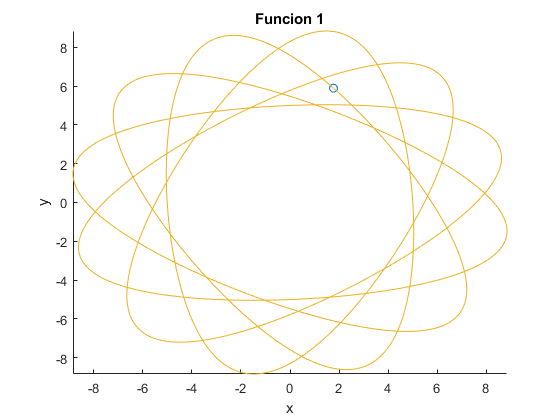

% Grafica la función paramétrica
t = 0:0.01:14*pi;    % Valores de la variable t
x = -2.*cos(t) + 7.*cos((5/7* t) - 1); % Posición en x
y = -2.*sin(t) - 7.*sin((5/7* t) - 1);  % Posición en y
comet(x,y);
xlabel('x')
ylabel('y')
title('Funcion 1')

#### Función 2

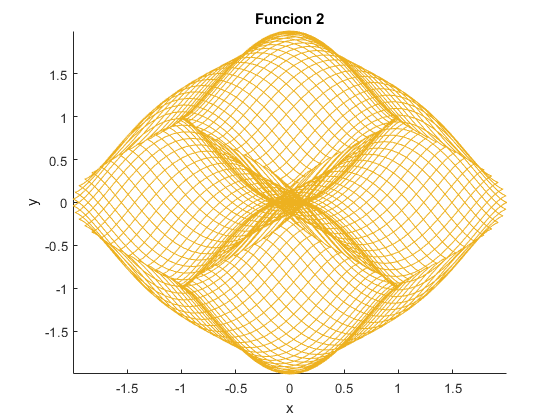

t = 0:0.001:2*pi;
x = cos(80*t)-cos(t).^3;
y = sin(t)-sin(80*t).^3;
comet(x, y)
xlabel('x')
ylabel('y')
title('Funcion 2')

#### Función 3

t = 0:0.001:4*pi

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


x = cos(2*t) - cos(200*t).^3

x =          0    0.0586    0.2186    0.4378    0.6618    0.8422    0.9523    0.9950    0.9999    1.0116    1.0719    1.2036    1.4007    1.6288    1.8361    1.9698    1.9944    1.9031    1.7205    1.4941    1.2785    1.1170    1.0281    1.0004    0.9982    0.9759    0.8958    0.7429    0.5319    0.3039    0.1130    0.0084    0.0183    0.1398    0.3406    0.5691    0.7723    0.9129    0.9813    0.9968    0.9999    1.0357    1.1365    1.3090    1.5297    1.7523    1.9222    1.9947    1.9502    1.8007


y = sin(200*t) - sin(t).^3

y =          0    0.1987    0.3894    0.5646    0.7174    0.8415    0.9320    0.9854    0.9996    0.9738    0.9093    0.8085    0.6755    0.5155    0.3350    0.1411   -0.0584   -0.2555   -0.4425   -0.6119   -0.7568   -0.8716   -0.9516   -0.9937   -0.9962   -0.9589   -0.8835   -0.7728   -0.6313   -0.4646   -0.2794   -0.0831    0.1165    0.3115    0.4941    0.6569    0.7936    0.8987    0.9679    0.9985    0.9893    0.9407    0.8545    0.7343    0.5848    0.4120    0.2228    0.0247   -0.1744   -0.3666


z = -3*t

z =          0   -0.0030   -0.0060   -0.0090   -0.0120   -0.0150   -0.0180   -0.0210   -0.0240   -0.0270   -0.0300   -0.0330   -0.0360   -0.0390   -0.0420   -0.0450   -0.0480   -0.0510   -0.0540   -0.0570   -0.0600   -0.0630   -0.0660   -0.0690   -0.0720   -0.0750   -0.0780   -0.0810   -0.0840   -0.0870   -0.0900   -0.0930   -0.0960   -0.0990   -0.1020   -0.1050   -0.1080   -0.1110   -0.1140   -0.1170   -0.1200   -0.1230   -0.1260   -0.1290   -0.1320   -0.1350   -0.1380   -0.1410   -0.1440   -0.1470


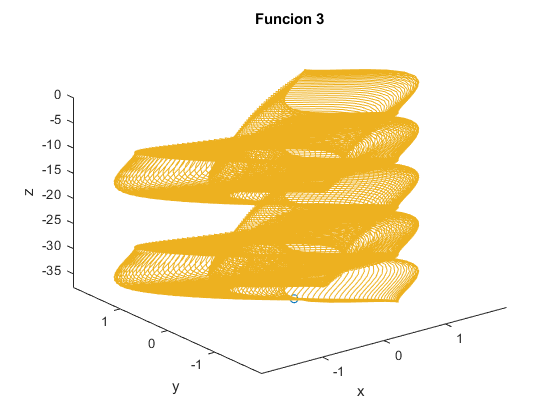

comet3(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Funcion 3')

#### Función 4

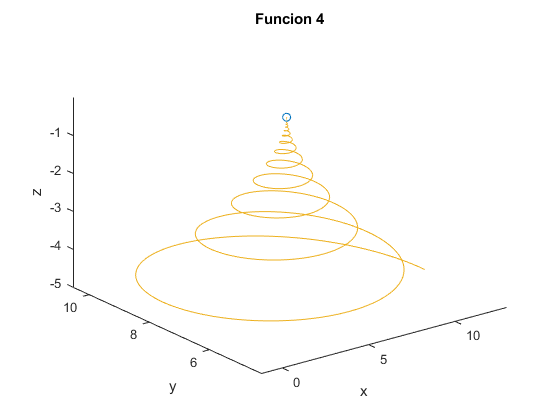

t = 0:0.01:10*pi;
x = 5+8*cos(5*t).*exp(-0.4*t);
y = 7+4*sin(5*t).*exp(-0.4*t);
z = -5*exp(-0.25*t);
comet3(x, y, z)
xlabel('x')
ylabel('y')
zlabel('z')
title('Funcion 4')

## Ejercicio 2

Grafiquen las siguientes superficies para los rangos de valores de xx , yy y zz  especificados. Utilicen diferentes colores para cada una de las superficies, e indiquen qué nombre le darían a cada figura.

#### Función 1

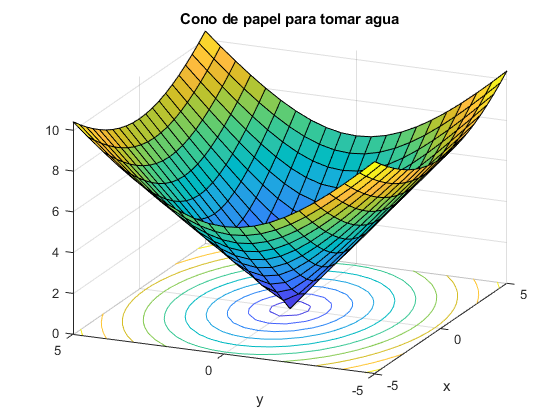

t=@(x,y)(5*(sqrt((x.^2/16)+(y.^2/9))));
x = -5:0.5:5;  % define range and mesh of x and y which will be shown in figure
y = -5:0.5:5;
[X, Y] = meshgrid(x, y);
surfc(X, Y, t(X,Y));
xlabel('x')
ylabel('y')
title('Cono de papel para tomar agua')

view([-66.3 25.0])

#### Función 2

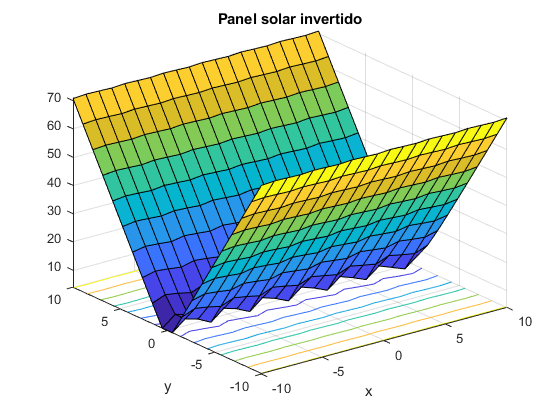

t = @(x,y)(5*sqrt(sin(2*x)+2*y.^2+1));
xl = linspace(-10,10,20);
yl = linspace(-10,10,20);
[X,Y] = meshgrid(xl,yl);
surfc(X, Y, t(X,Y));
xlabel('x');
ylabel('y');
title('Panel solar invertido');

#### Función 3

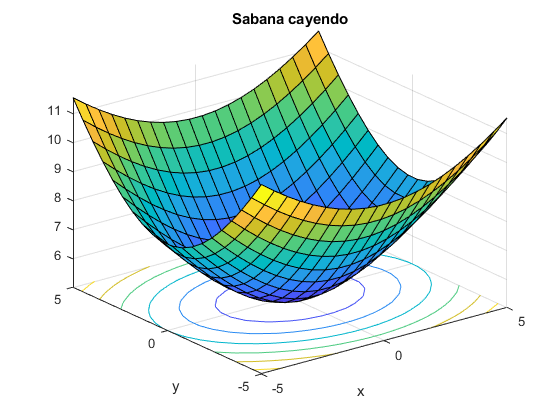

t = @(x,y)(5*sqrt((x.^2/16)+(y.^2/9)+(1)));
xl = linspace(-5,5,20);
yl = linspace(-5,5,20);
[x,y] = meshgrid(xl,yl);
surfc(x,y,t(x,y));
xlabel('x');
ylabel('y');
title('Sabana cayendo');

#### Función 4

t = @(x,y)((x.^3+y.^3+2).^(1/3))

t = function_handle with value:
    @(x,y)((x.^3+y.^3+2).^(1/3))


xl = linspace(-1,1,20)

xl =    -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000


yl = linspace(-1,1,20)

yl =    -1.0000   -0.8947   -0.7895   -0.6842   -0.5789   -0.4737   -0.3684   -0.2632   -0.1579   -0.0526    0.0526    0.1579    0.2632    0.3684    0.4737    0.5789    0.6842    0.7895    0.8947    1.0000


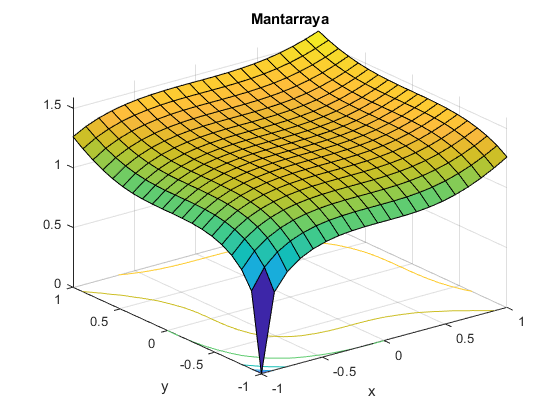

[X,Y] = meshgrid(xl,yl);
surfc(X, Y, t(X,Y))
xlabel('x')
ylabel('y')
title('Mantarraya')

## Ejercicio 3

Investiguen cuál es el campo eléctrico producido por una linea de carga infinita que está a lo largo del eje z, y grafiquen el campo eléctrico en el plano X-Y que se obtendría para una línea de carga con densidad de 6 nC/m

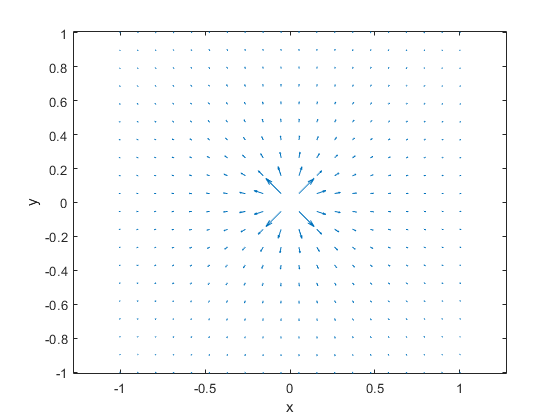

[x, y] = meshgrid(xl, yl);   % Retícula de puntos

% Constantes
K = 8.99e9;
lambda = 6e-9;

%Campo eléctrico
Ex = (2*K*lambda./(x.^2 + y.^2)).*x;
Ey = (2*K*lambda./(x.^2 + y.^2)).*y;

h = quiver(x, y, Ex, Ey);

axis equal
xlabel('x')
ylabel('y')

## Ejercicio 4

Grafiquen el campo eléctrico que se obtiene por dos cargas eléctricas en el espacio, una de 9 nC, y otra de -6 nC, colocadas en las siguiente posiciones:

Carga 1: x = -0.05 m, y = 0.00 m, z = -0.05 m

Carga 2: x = 0.05 m, y = 0.00 m, z = 0.05 m

Seleccionen el rango de graficación que consideren adecuado para este problema.

Nota: puede agregar puntos que representen las cargas utilizando la función **scatter3**.

% Propiedades de la carga 1
q1 = 9e-6;       
xq1 = -0.05;
yq1 = 0.00;
zq1 = -0.05

zq1 = -0.0500


% Propiedades de la carga 2
q2 = -6e-6;       
xq2 = 0.05;
yq2 = 0.00;
zq2 = 0.05

zq2 = 0.0500

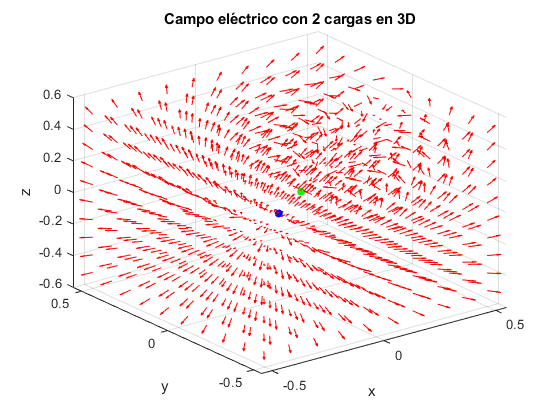


% Posiciones donde vamos a evaluar el campo eléctrico
xl = linspace(-0.5, 0.5, 10);
yl = linspace(-0.5, 0.5, 10);
zl = linspace(-0.5, 0.5, 10);
[x, y, z] = meshgrid(xl, yl, zl);

[Ex1, Ey1, Ez1] = electric_field3(q1, xq1, yq1, zq1,x, y,z);
[Ex2, Ey2, Ez2] = electric_field3(q2, xq2, yq2, zq2,x, y,z);
Ex = Ex1 + Ex2; 
Ey = Ey1 + Ey2;
Ez = Ez1 + Ez2;

E = sqrt(Ex.^2 + Ey .^2 + Ez.^2);

quiver3(x, y, z, Ex./E, Ey./E,Ez./E, 0.5, 'linewidth', 0.5, 'color', 'r')
xlabel('x')
ylabel('y')
zlabel('z')
title('Campo eléctrico con 2 cargas en 3D')

hold on
scatter3(xq1, yq1, zq1 ,'b', 'filled', 'LineWidth',2)
scatter3(xq2, yq2, zq2 ,'g', 'filled', 'LineWidth',2)
hold off

## Ejercicio 5

load 'superficie misteriosa.mat'

**a) **Grafique la superficie con una paleta de colores **autum **agregando la siguiente instrucción antes de llamar a la función **surf**.

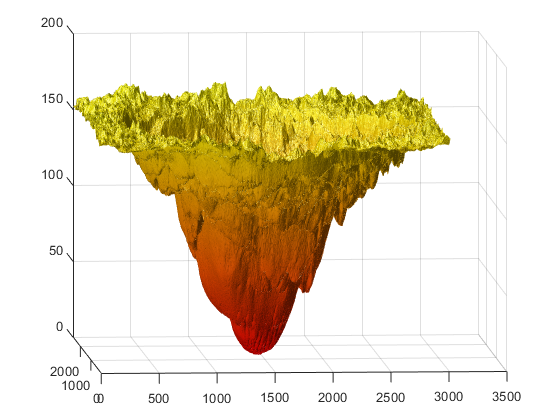

colormap autumn


surf(x,y,z,'EdgeColor','none');

 ¿Qué creen que representa la superficie? 

- Podemos observar una tipo mina , o un crater, tambien podria ser la boca de un volcan.

¿Qué función realiza la instrucción **colormap**? 

- Colormap utiliza una paleta de colores en donde cada color permite representar de forma mas grafica y entendible la superficie a dibujar, esta instruccion cuenta con paletas de colores ya establecidas con un nombre.Por ejemplo se puede usar colores mas oscuros en donde el ojo humano esperaria ver sombras y colores mas claros a superficies con luz, dando una ilusion de profundidad a la superficie.La paleta de colores tambien pueden variar , segun los valores.

**b) **Investiguen qué otras paletas de colores hay disponibles en MATLAB, y pruebe al menos otras 5 con la superficie de este ejercicio. 

1)

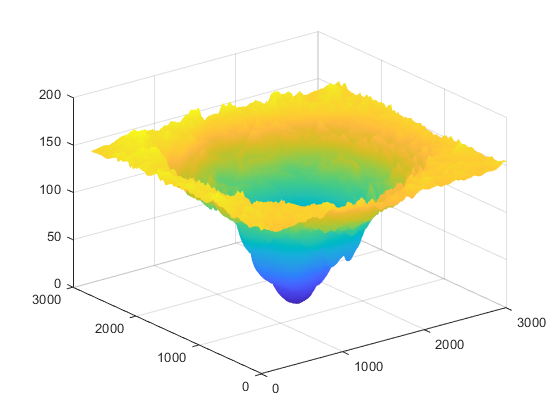

colormap parula


surf(x,y,z,'EdgeColor','none');

2)

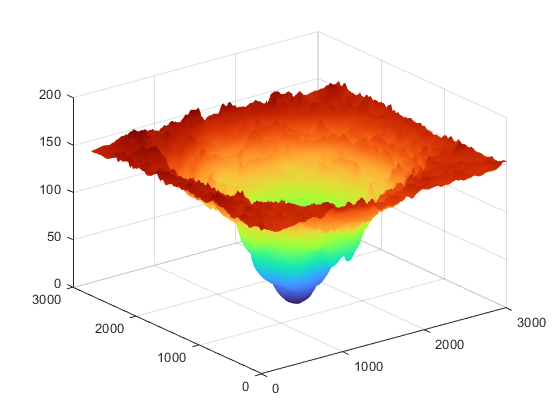

colormap turbo


surf(x,y,z,'EdgeColor','none');

3)

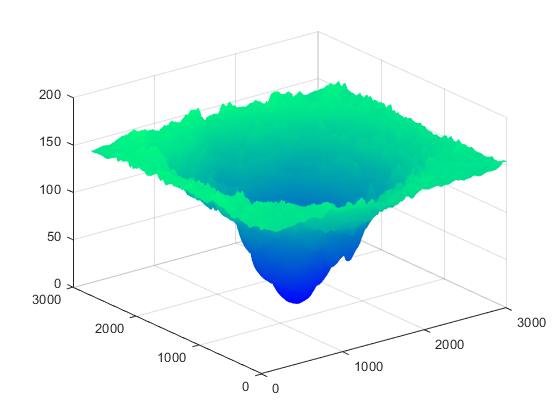

colormap winter


surf(x,y,z,'EdgeColor','none');

4)

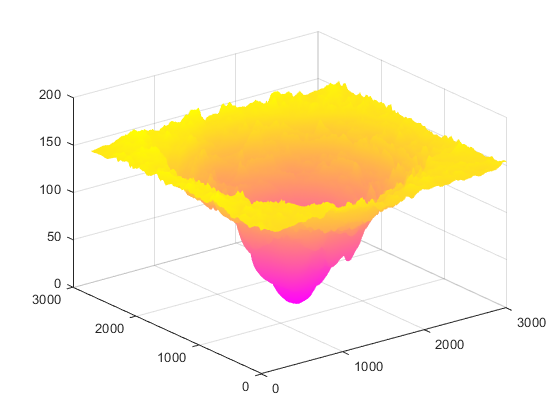

colormap spring


surf(x,y,z,'EdgeColor','none');

5)

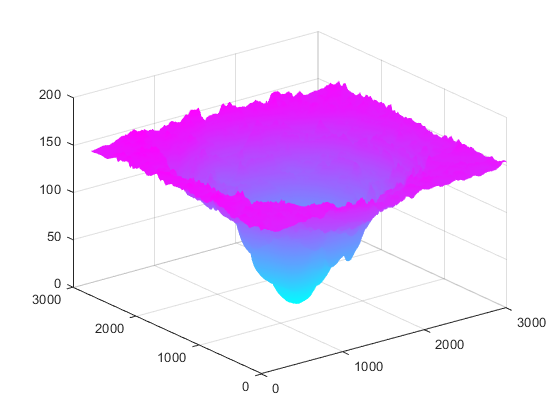

colormap cool


surf(x,y,z,'EdgeColor','none');

¿Con cuál consideran que se obtienen mejores resultados?

- Con el "turbo" pudimos distinguir mas los valores ademas de que personalmente los colores se ven muy bien y nos gustan

**c)**  Agreguen las siguientes instrucciones después de llamar a la función **surf**. 

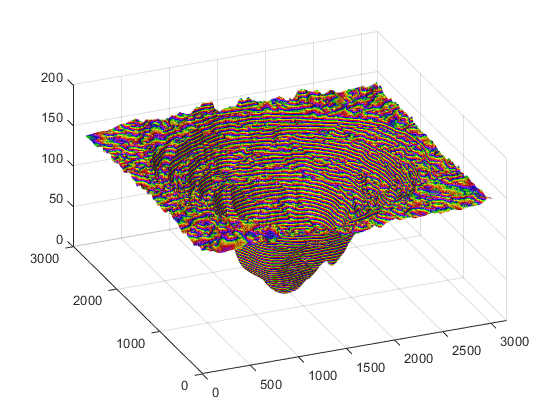

load 'superficie misteriosa.mat'

colormap turbo
surf(x,y,z,'EdgeColor','none');

view(0,75)
shading interp
lightangle(-45,30)

s.FaceLighting = 'gouraud';
s.AmbientStrength = 0.3;
s.DiffuseStrength = 0.8;
s.SpecularStrength = 0.9;
s.SpecularExponent = 25;
s.BackFaceLighting = 'unlit';

¿Qué efecto tienen dichas instrucciones?

- Cambia la perspectiva en la que se ve la superficie. Nos permite ver más el interior y le da efectos lumínicos y profundidad a la imagen para un mejor entendimiento de esta. 

## Función para campo eléctrico en 3D

function [Ex, Ey, Ez] = electric_field3(q, xq, yq, zq, x, y, z)
% Calcula el campo eléctrico en los puntos x, y, x debido a una carga puntual 
% localizada en (xq, yq, zq) . Regresa los valores de las componentes Ex Ey
% Ez
% del campo.

% Calcula el campo eléctrico
k = 1/(4*pi*8.8541878176e-12);
rx = x - xq;
ry = y - yq;
rz = z - zq;
r = sqrt(rx.^2 + ry.^2 + rz.^2);

Ex = k*q*rx./(r.^3);
Ey = k*q*ry./(r.^3);
Ez = k*q*rz./(r.^3);

end
